# HW 11 - Ch 14 - Linear Regression

## Prob 1

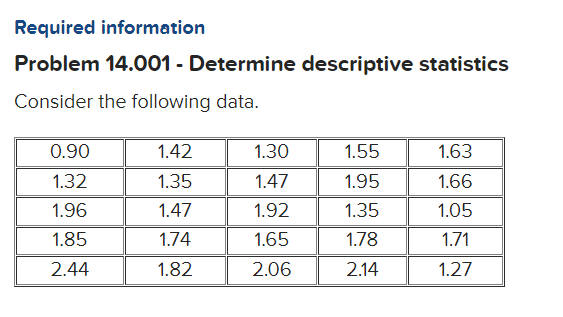

Determine the mean, median, mode, and range for the given data.

% A = [0.90 1.42 1.30 1.55 1.63; 
%      1.32 1.35 1.47 1.95 1.66; 
%      1.96 1.47 1.92 1.35 1.05; 
%      1.85 1.74 1.65 1.78 1.71; 
%      2.44 1.82 2.06 2.14 1.27] % suboptimal - should just be row

A = [0.90 1.42 1.30 1.55 1.63...  
     1.32 1.35 1.47 1.95 1.66... 
     1.96 1.47 1.92 1.35 1.05... 
     1.85 1.74 1.65 1.78 1.71... 
     2.44 1.82 2.06 2.14 1.27];

avg = mean(A)

avg =                     1.6304


med = median(A)

med =                       1.65


% [M,F] = mode(A) % FAILS: only designed for having 1 mode - use hist instead
ran = range(A)

ran =                       1.54



s = size(A)

s =      1    25


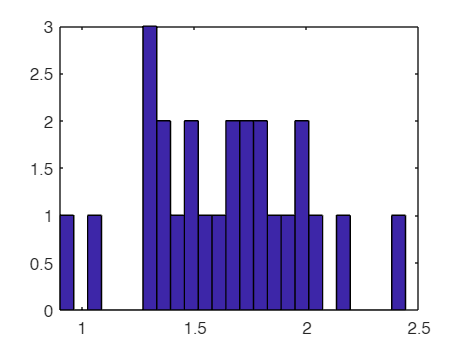

%help mode
hist(A, s(2))

help hist % apparently outdated

 hist  Histogram.
    hist is not recommended. Use HISTOGRAM or HISTCOUNTS instead.
  
    N = hist(Y) bins the elements of Y into 10 equally spaced containers
    and returns the number of elements in each container.  If Y is a
    matrix, hist works down the columns.
 
    N = hist(C) returns the category counts for the categorical array C.
    For a categorical matrix, hist works down the columns of Y and returns
    a matrix of counts with one column for each column of Y and one row for
    each category.
 
    N = hist(Y,M), where M is a scalar, uses M bins.
 
    N = hist(Y,X), where X is a vector, returns the distribution of Y among
    bins with centers specified by X. The first bin includes data between
    -inf and the first center and the last bin includes data between the
    last bin and inf. Note: Use HISTC if it is more natural to specif

help histcounts

 histcounts - Histogram bin counts
    This MATLAB function partitions the X values into bins and returns the
    bin counts and the bin edges.

    Syntax
      [N,edges] = histcounts(X)
      [N,edges] = histcounts(X,nbins)
      [N,edges] = histcounts(X,edges)
      [N,edges,bin] = histcounts(___)

      N = histcounts(C)
      N = histcounts(C,Categories)
      [N,Categories] = histcounts(___)

      [___] = histcounts(___,Name,Value)

    Input Arguments
      X - Data to distribute among bins
        vector | matrix | multidimensional array
      C - Categorical data
        categorical array
      


[N,edges] = histcounts(A, s(2))

N =      1     0     1     0     0     1     2     2     1     2     1     1     2     2     2     1     2     1     1     0     1     0     0     0     1


edges =                        0.9                     0.962                     1.024                     1.086                     1.148                      1.21                     1.272                     1.334                     1.396                     1.458                      1.52                     1.582                     1.644                     1.706                     1.768                      1.83                     1.892                     1.954                     2.016                     2.078                      2.14                     2.202                     2.264                     2.326                     2.388                      2.45


Std way

% Mode (use the script from the previous answer for multi-modal data)
[unique_vals, ~, idx] = unique(A);
counts = accumarray(idx, 1);
modes = unique_vals(counts == max(counts))

modes =                       1.35                      1.47


## Prob 2

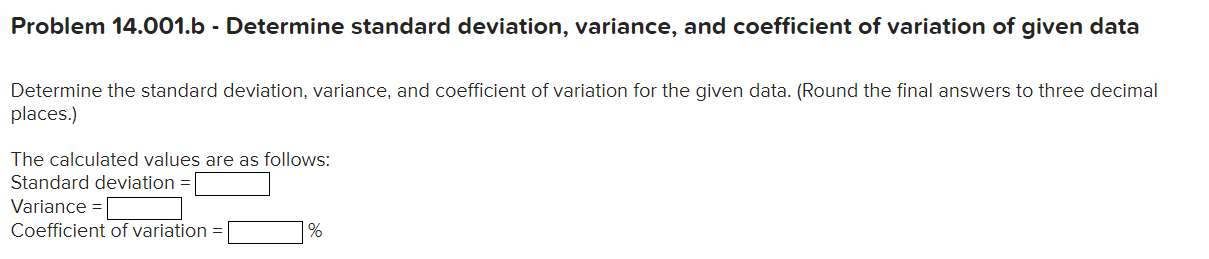

## Prob 3

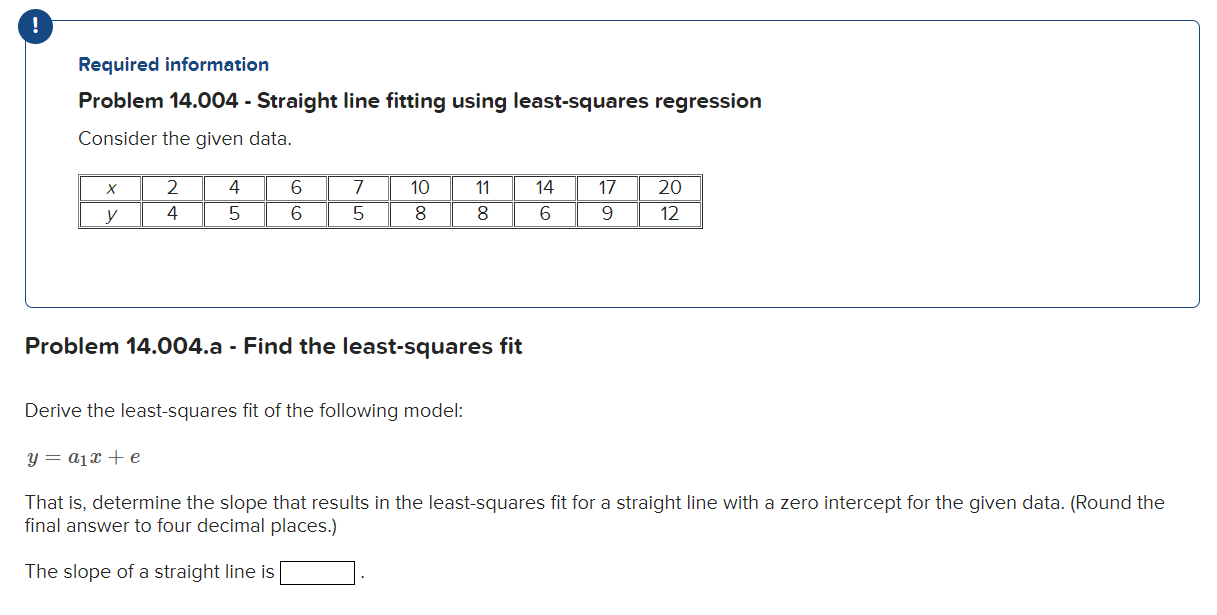

## Prob 4

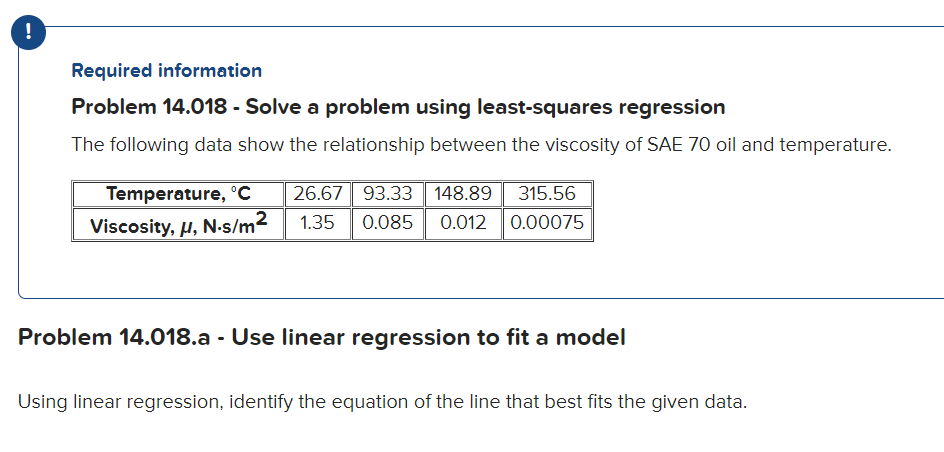

## Prob 5

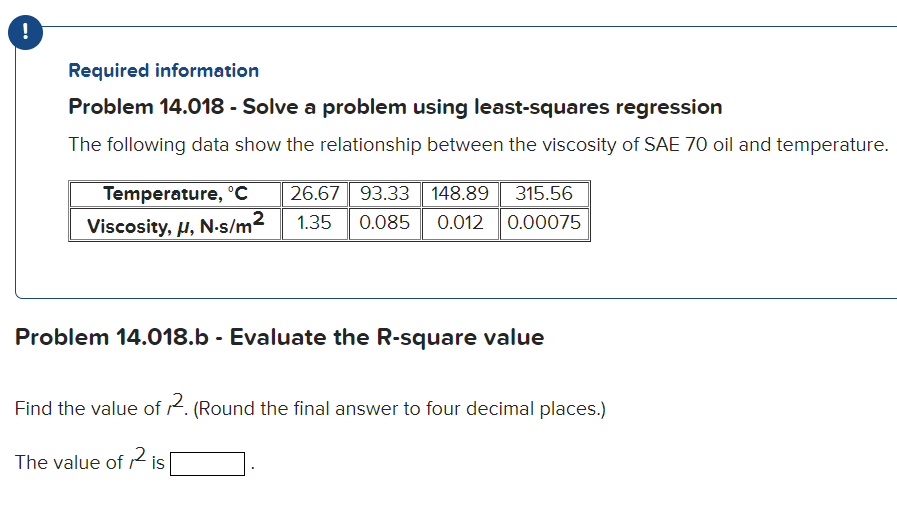

## Prob 6

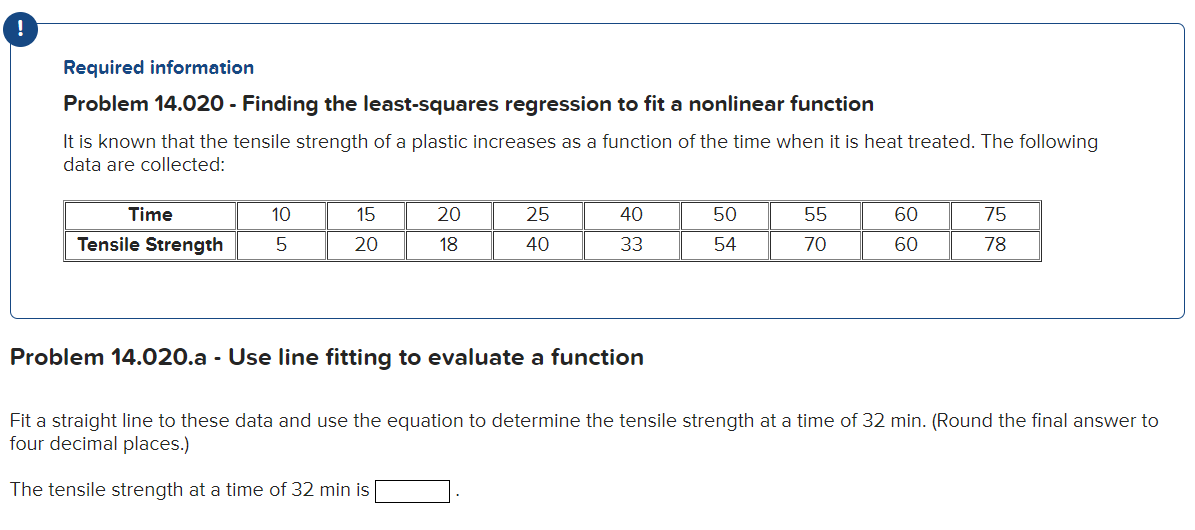

## Prob 7